%clear all
%Lectura matriu de digits
N=100;
[images, labels] =readMNIST( ...
    'train-images-idx3-ubyte\train-images.idx3-ubyte', ...
    'train-labels-idx1-ubyte\train-labels.idx1-ubyte',N,0);

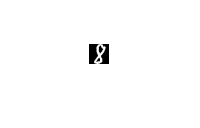

Nft = 3112;
count = 0;
vartypes = strings([1,Nft+1]);
vartypes{Nft+1} = 'string';
vartypes(1:Nft) = 'double';
T = table('Size',[N Nft+1],'VariableTypes',vartypes);



for i = 1:N
    im=images(:,:,i); 
    imshow(im)
    [sumRow,sumCol,distRowLeft,distRowRight,distColUp,distColDown,diffRowLeft,diffRowRight,diffColUp,diffColDown] = features(im);
    
    T{i,1:20} = sumRow;
    T{i,21:40} = sumCol;
    T{i,41:60} = distRowLeft;
    T{i,61:80} = distRowRight;
    T{i,81:100} = distColUp;
    T{i,101:120} = distColDown;
    T{i,121:139} = diffRowLeft;
    T{i,140:158} = diffRowRight;
    T{i,159:177} = diffColUp;
    T{i,178:196} = diffColDown;

    [hog_2x2, vis2x2] = extractHOGFeatures(im,'CellSize',[2 2]);
    T{i,197:3112} = hog_2x2;
    T.Var3113(i)=labels(i);
%     count = count + 1;
%     if (mod(count,10) == 0)
%         count
%     end
end

Nft = 3112;
idx = fscchi2(T,'Var3113');
Nred = 0.26 * Nft;
Nred = int16(Nred);
T2 = reduirDescriptors(idx,T,Nred,Nft);

tic
[res, results] = getDigit(images, labels, trainedModel);
timeElapsed = toc

timeElapsed = 8.0683